### **Data extraciton - no step delay**



Input_voltage_toAnalyse = Input_voltage_step.Data;
Output_speed_toAnalyse = Output_Speed.Data;

plot(tout,Input_voltage_toAnalyse);
title("Step response of real system");
xlim([0 0.3]);
ylim([0 400]);

hold on 
plot(tout,Output_speed_toAnalyse);


### **Transfer function - No zeros analisys**

sys = tf(Transfer_function_2_noDelay_NOZEROS)

sys =
 
  From input "u1" to output "y1":
         4.732e05
  ----------------------
  s^2 + 4032 s + 1.93e05
 
Name: Transfer_function_2_noDelay_NOZEROS
Continuous-time transfer function.
Model Properties


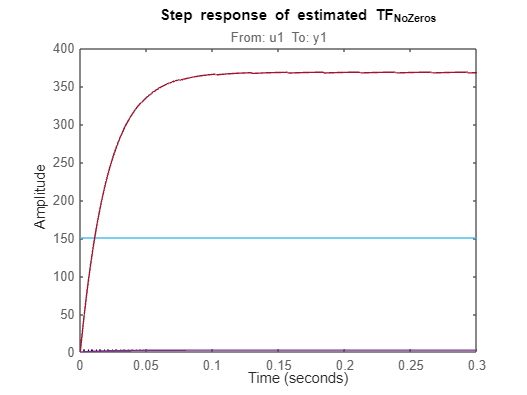

title("Step response of estimated TF_NoZeros");
step(sys, 0.3);